%% Load image data
% This assumes you have a directory: Scene_Categories
% with each scene in a subdirectory
imds = imageDatastore('C:\Users\Shreyas Desai\Desktop\test\sce',...
    'IncludeSubfolders',true,'LabelSource','foldernames')              %#ok

imds =   ImageDatastore with properties:

                       Files: {
                              'C:\Users\Shreyas Desai\Desktop\test\sce\01 (10).jpg';
                              'C:\Users\Shreyas Desai\Desktop\test\sce\01 (11).jpg';
                              'C:\Users\Shreyas Desai\Desktop\test\sce\01 (12).jpg'
                               ... and 36 more
                              }
                     Folders: {
                              'C:\Users\Shreyas Desai\Desktop\test\sce'
                              }
                      Labels: [sce; sce; sce ... and 36 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


%imds.ReadFcn = @readAndResizeImages;

Dispplay labels

%% Display Class Names and Counts
tbl = countEachLabel(imds)                                             %#ok

tbl = 1×2 table
    Label    Count
    _____    _____

     sce      39  


categories = tbl.Label;

siufeuif

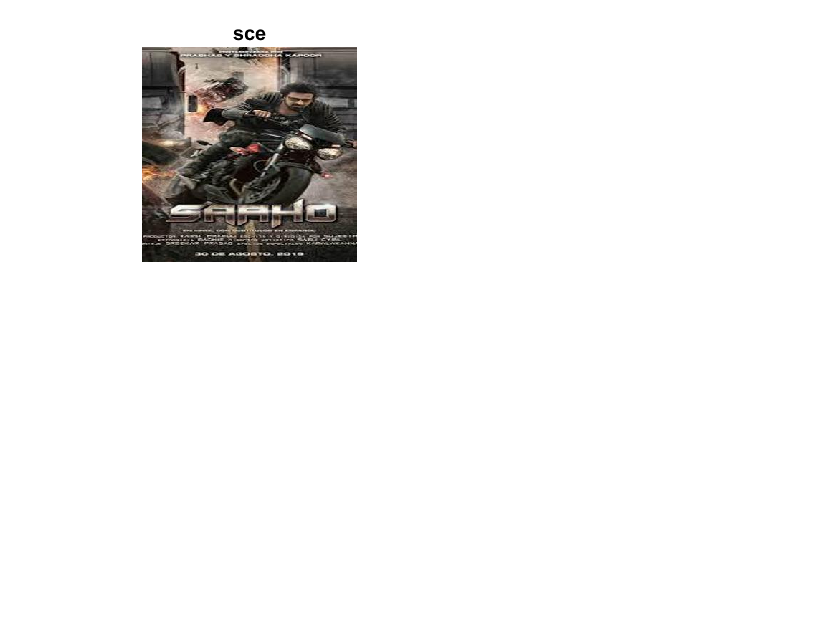

%% Display Sampling of Image Data
visImds = splitEachLabel(imds,1,'randomize');

for ii = 1:1 % this assumes 4 categories of scenes
    subplot(2,2,ii);
    imshow(visImds.readimage(ii));
    title(char(visImds.Labels(ii)));
end

ssaC

%% Partition 700 images for training and 200 for testing
[training_set, test_set] = imds.splitEachLabel(20,13,'randomize',true);

Bag of features

%% Create Visual Vocabulary 
tic
bag = bagOfFeatures(training_set,'VocabularySize',100,'PointSelection','Detector');

Creating Bag-Of-Features.
-------------------------
* Image category 1: sce
* Selecting feature point locations using the Detector method.
* Extracting SURF features from the selected feature point locations.
** detectSURFFeatures is used to detect key points for feature extraction.

* Extracting features from 20 images...done. Extracted 7707 features.

* Keeping 80 percent of the strongest features from each category.

* Balancing the number of features across all image categories to improve clustering.
** Image category 1 has the least number of strongest features: 6166.
** Using the strongest 6166 features from each of the other image categories.

* Using K-Means clustering to create a 100 word visual vocabulary.
* Number of features          : 6166
* Number of clusters (K)      : 100

* Initializing cluster centers...100.00%.
* Clustering...completed 23/100 iterations (~0.17 sec

scenedata = double(encode(bag, training_set));

Encoding images using Bag-Of-Features.
--------------------------------------
* Image category 1: sce
* Encoding 20 images...done.


toc

Elapsed time is 8.131047 seconds.


Visualize 

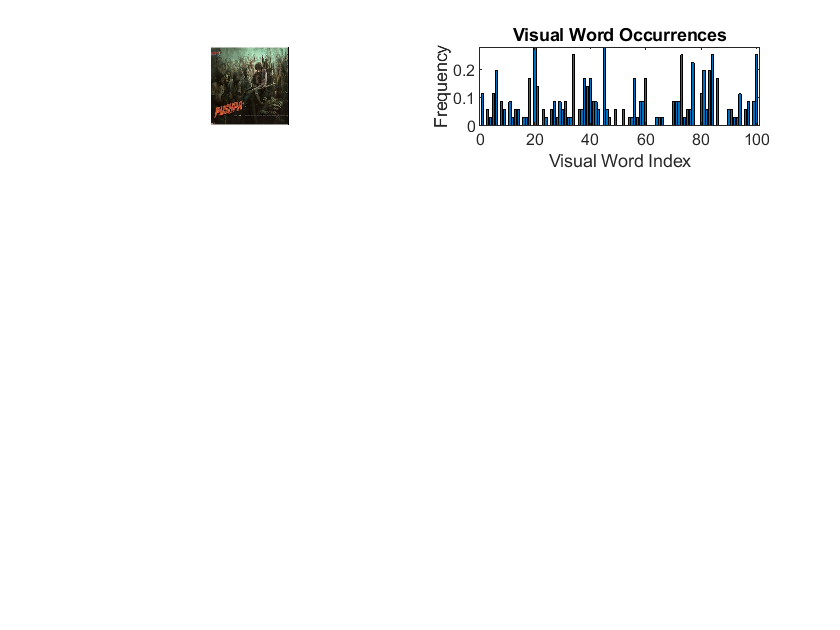

%% Visualize Feature Vectors
imgs = training_set.splitEachLabel(1,'randomize',true);

img = readimage(imgs,1);
featureVector = encode(bag, img);
subplot(4,2,1); imshow(img);
subplot(4,2,2);
bar(featureVector);title('Visual Word Occurrences');xlabel('Visual Word Index');ylabel('Frequency');


%{
img = readimage(imgs,2);
featureVector = encode(bag, img);
subplot(4,2,3); imshow(img);
subplot(4,2,4); 
bar(featureVector);title('Visual Word Occurrences');xlabel('Visual Word Index');ylabel('Frequency');

img = readimage(imgs,3);
featureVector = encode(bag, img);
subplot(4,2,5); imshow(img);
subplot(4,2,6); 
bar(featureVector);title('Visual Word Occurrences');xlabel('Visual Word Index');ylabel('Frequency');

img = readimage(imgs,4);
featureVector = encode(bag, img);
subplot(4,2,7); imshow(img);
subplot(4,2,8); 
bar(featureVector);title('Visual Word Occurrences');xlabel('Visual Word Index');ylabel('Frequency');
%}

uvcuid

SceneImageData = array2table(scenedata);
%sceneType = categorical(repelem({training_set.Description}', [training_set.Count], 1));
SceneImageData.sceneType = training_set.Labels;

WBCHUB S

%% Use the new features to train a model and assess its performance using 
classificationLearner